c1=1;
c2=2;
k1=3;
k2=4;
m1=5;
m2=6;
F=7;


%transmitnce
M=[m1 0;0 m2];
C2=[c1 -c1;-c1 (c1+c2)];
K=[k1 -k2;-k1 k1+k2];

%transmittance
s = tf('s');
H2 = 1/(M.*s^2+C2.*s+K)

H2 =
 
  From input 1 to output...
              0.2 s^2 + 0.1 s + 0.2333
   1:  ---------------------------------------
       s^4 + 0.7 s^3 + 1.833 s^2 + 0.3 s + 0.3
 
                   0.03333 s + 0.1
   2:  ---------------------------------------
       s^4 + 0.7 s^3 + 1.833 s^2 + 0.3 s + 0.3
 
  From input 2 to output...
                 0.03333 s + 0.1333
   1:  ---------------------------------------
       s^4 + 0.7 s^3 + 1.833 s^2 + 0.3 s + 0.3
 
            0.1667 s^2 + 0.03333 s + 0.1
   2:  ---------------------------------------
       s^4 + 0.7 s^3 + 1.833 s^2 + 0.3 s + 0.3
 
Continuous-time transfer function.




%state
A=[c1/m1 0 k1/m1 0; c1/m1 (-c1-c2)/m2 k1/m2 (-k1-k2)/m2;
    1 0 0 0; 0 1 0 0];
B=[1/m1;0;0;0];
C=[0 0 1 0; 0 0 0 1];
D=[0];
%state space
sys = ss(A,B,C,D);
H=tf(sys)

H =
 
  From input to output...
              0.2
   1:  -----------------
       s^2 - 0.2 s - 0.6
 
                      0.04 s + 0.1
   2:  -------------------------------------------
       s^4 + 0.3 s^3 + 0.4667 s^2 - 0.5333 s - 0.7
 
Continuous-time transfer function.



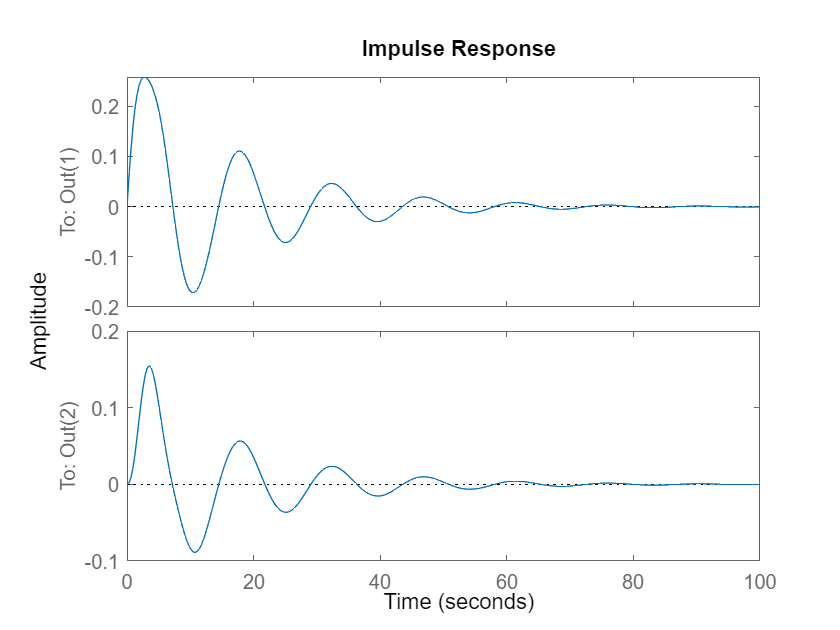

figure(1)
impulse(H2(:,1))

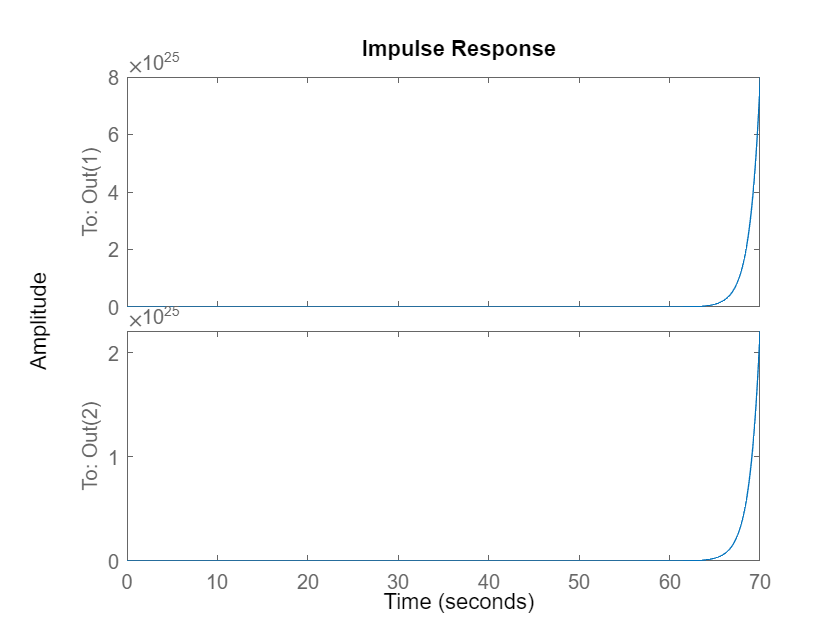

figure(2)
impulse(H)

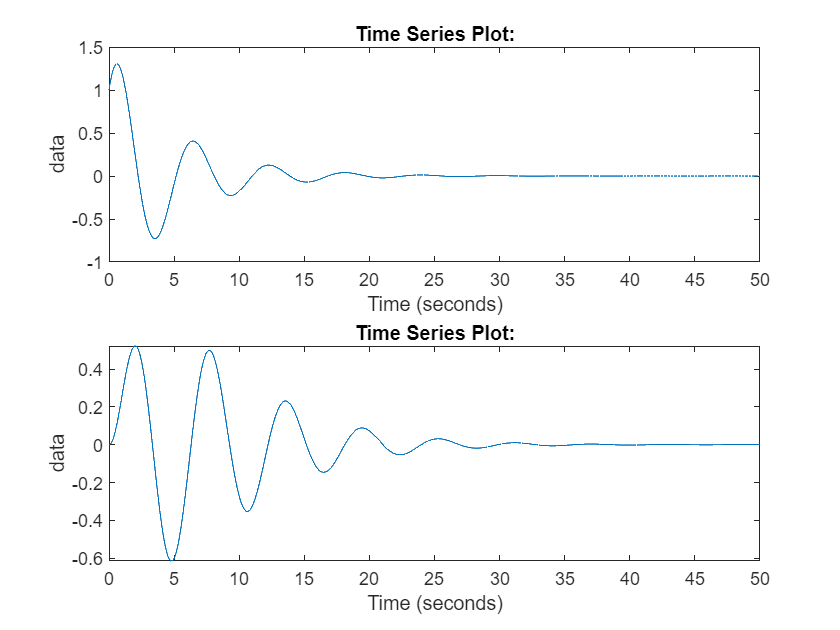

out=sim("reportsim.slx");

figure(3)
subplot(2,1,1)
plot(out.impulse1);
subplot(2,1,2)
plot(out.impulse2);

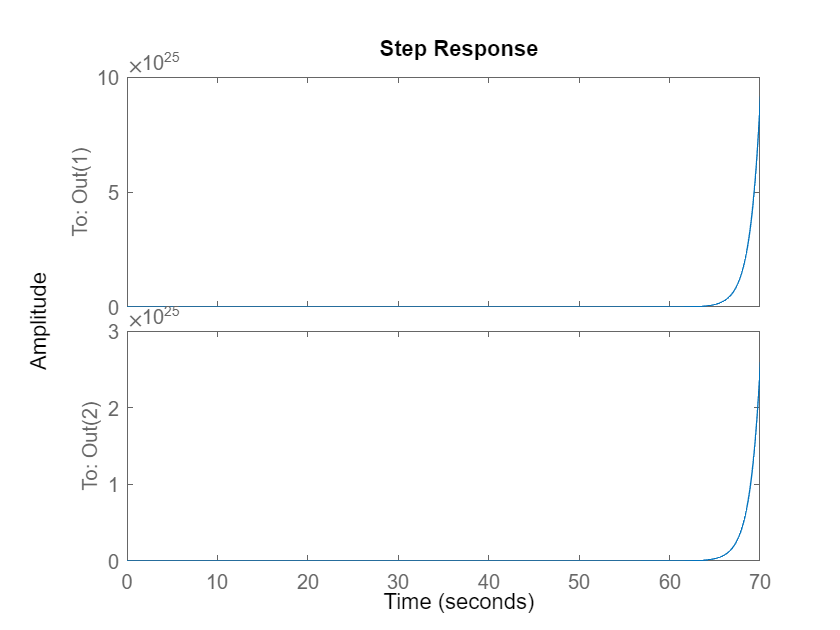

figure(4)
step(H(:,1))

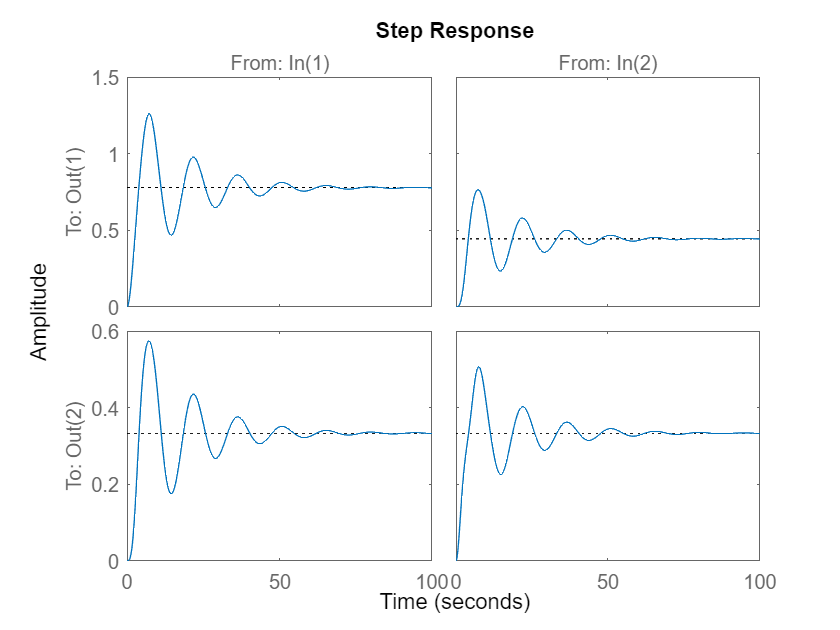

figure(5)
step(H2)

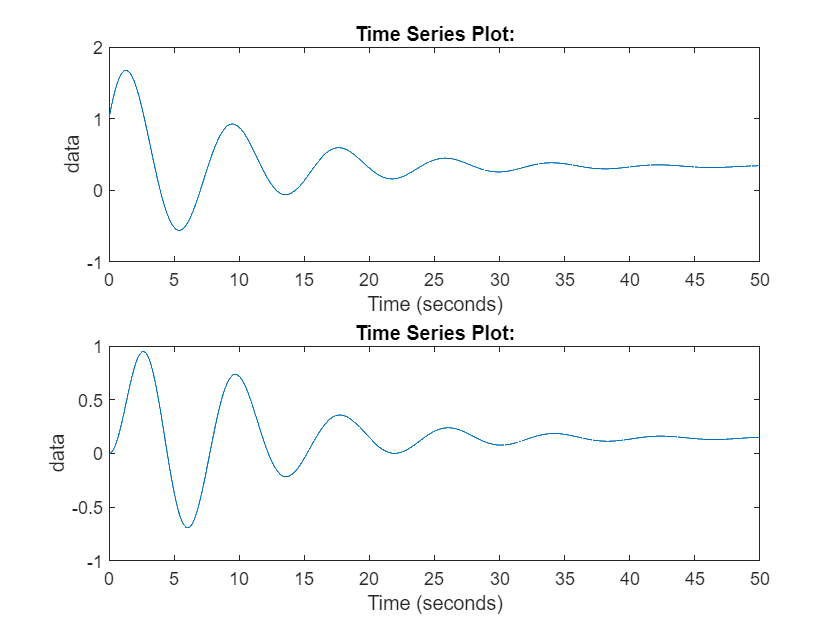

figure(6)
subplot(2,1,1)
plot(out.step1);
subplot(2,1,2)
plot(out.step2);

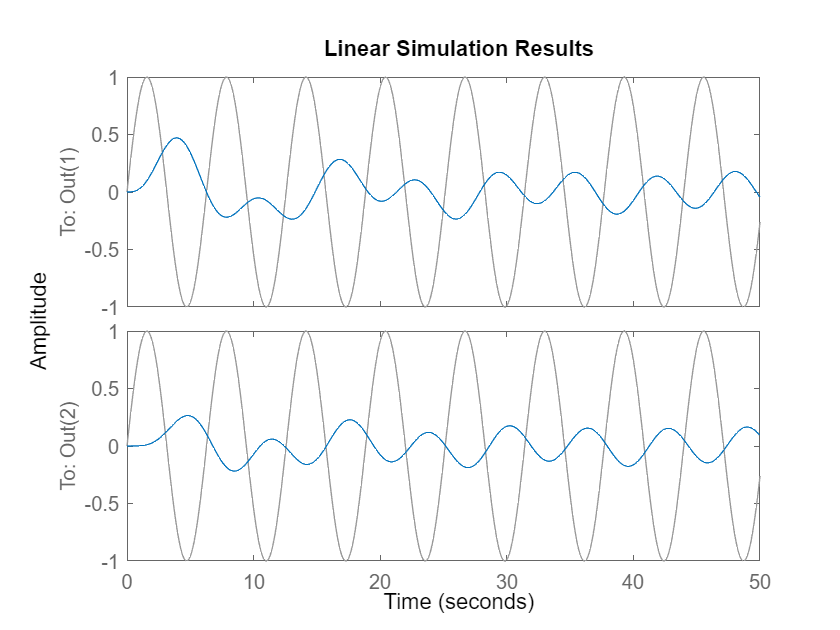

figure(7)
t=0:0.1:50;
y=sin(t);
lsim(H2(:,1),y,t);

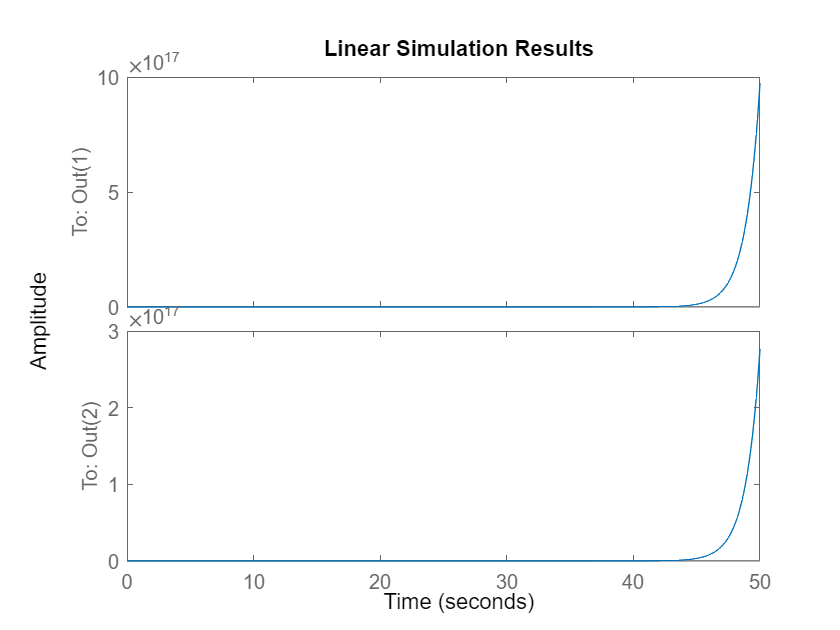

figure(8)
lsim(H(:,1),y,t);

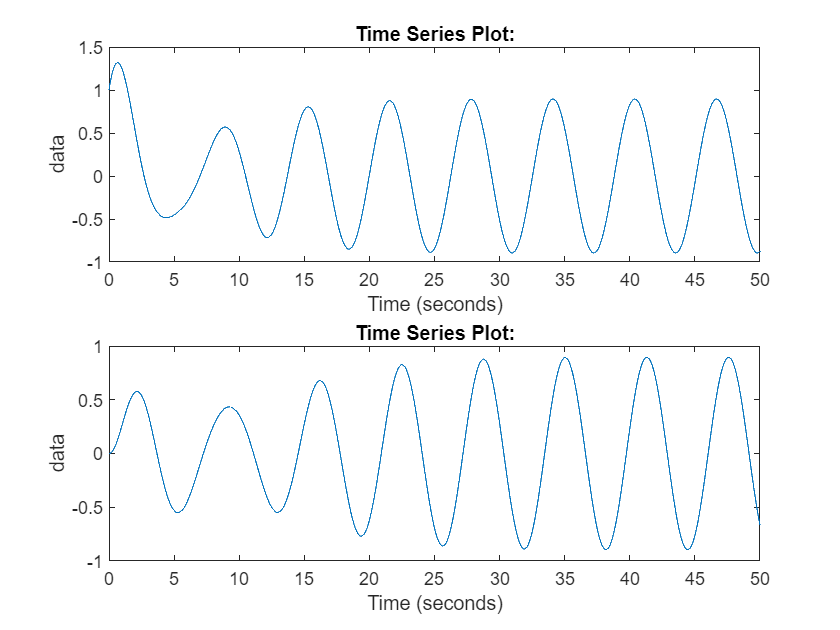

figure(9)
subplot(2,1,1)
plot(out.sin1);
subplot(2,1,2)
plot(out.sin2);

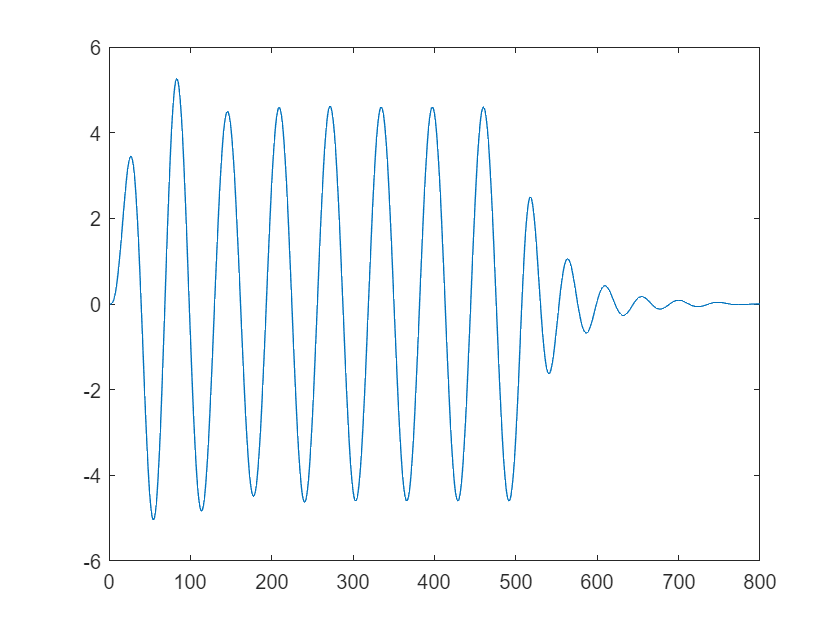

figure(10);
[Y,T] = impulse(H2);
x=conv(y,Y(:,1));
 plot(x)